% electrical constants and derived quantities for typical 
% mammalian dendrite
% Dimensions of compartments
d1 = 75e-4; % cm
d21 = 30e-4; % cm
d22 = 15e-4; % cm
%d21 = 47.2470e-4; % E9 cm
%d22 = d21; % E9 cm
l1 = 1.5; % dimensionless
l21 = 3.0; % dimensionless
l22 = 3.0; % dimensionless
% Electrical properties of compartments
Rm = 6e3; % Ohms cm^2
Rc = 90; % Ohms cm
Rs = 1e6; % Ohms
c1 = 2*(Rc*Rm)^(1/2)/pi;
rl1 = c1*d1^(-3/2); % Ohms
rl21 = c1*d21^(-3/2); % Ohms
rl22 = c1*d22^(-3/2); % Ohms
% Applied current
iapp = 1e-9; % Amps
% Coefficient matrices
A = [1 -1 0 0 0 0;
 0 0 exp(-l21) exp(l21) 0 0;
 0 0 0 0 exp(-l22) exp(l22);
 exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
 0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
 -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];
b = [rl1*iapp 0 0 0 0 0]';

## Question 03

x=A\b;
display(x);

x =     0.0007
    0.0000
    0.0011
   -0.0000
    0.0011
   -0.0000


## Question 04

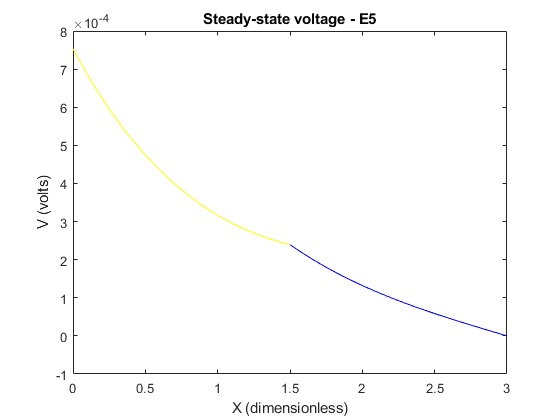

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

**The red line is not visible in the diagram, indicating it is either equal to or very close to the blue line. Since the yellow line (the parent branch's membrane potential) does not affect the daughter branches, it is concluded that the red and blue lines are equal. Therefore, the steady state voltage profiles of the two daughter branches are identical.**

**The code also supports this conclusion by plotting the red and blue lines, with the red line being hidden by the blue line, confirming their equality and the identical voltage profiles of the branches. Additionally, it mentions that the plots of and the plots of seem to be identical, which further supports the conclusion. As a result, the steady state voltage profile through the two daughter branches is equal.**

## Question 05

A_a=A;
b_a=b;


$$(i) \quad \left( \frac{d}{dX} V_{21} \right)_{x=L_{21}} = 0;\\


-A_{21} e^{-L_{21}} + B_{21} e^{-L_{21}} = 0 \quad \longrightarrow \quad (3'')$$


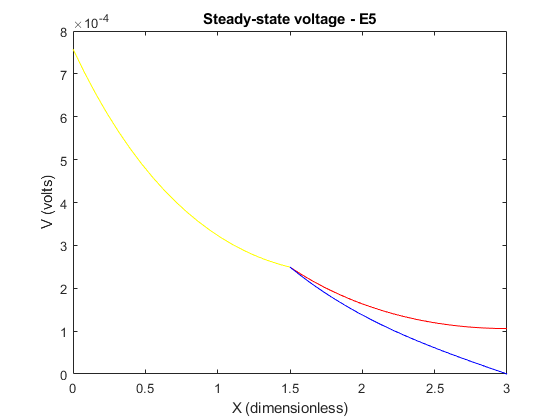

A_a(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$(ii) \left(\frac{d V_2}{dx}\right)_{x=l_2} = 0; \qquad\\ -A_2e^{-l_2} + B_2e^{l_2} = 0 \qquad \longrightarrow (4')$$


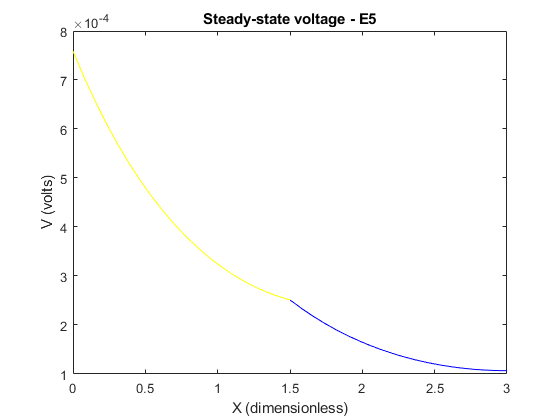

A_a(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$(iii) \left(\frac{d V_1}{dx}\right){x=0} = 0; \qquad\\  -A_1 + B_1 = 0 \qquad \longrightarrow (1')\\
\left(\frac{d V_1}{dx}\right){x=l_1} = (r'_b)1I{app}; \qquad\\ -A_1e^{-l_1} + B_1e^{l_1} = (r'_b)1I{app} \qquad \longrightarrow (3')$$


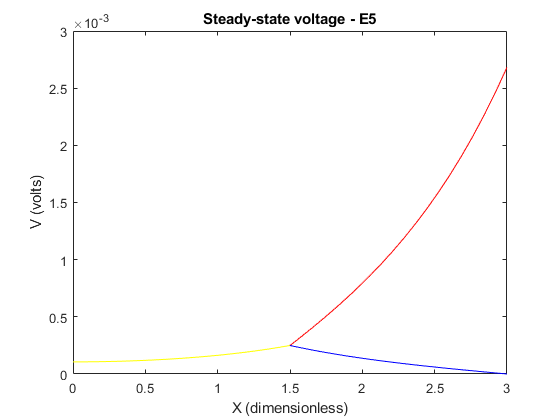

b(1) = 0; b(2) = rl21*iapp;
A_a(3,:) = A(3,:);
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$(iv) \left(\frac{d V_2}{dx}\right)_{x=l_2} = (r'_b)2I{app}; \qquad\\ -A_2e^{-l_2} + B_2e^{l_2} = (r'_b)2I{app} \qquad \longrightarrow (3')$$


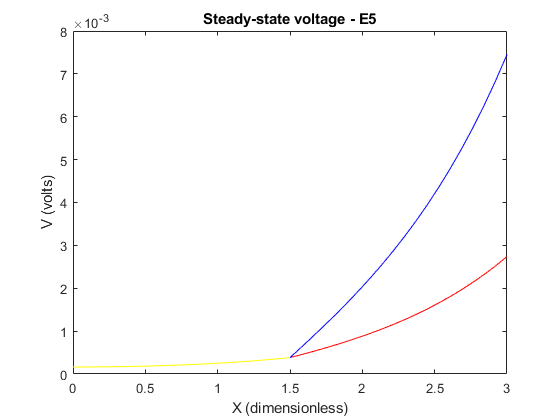

b(3) = rl22*iapp;
A_a(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

**The positive right hand sides of dV^2/dx for x=L/21 and x=L/22 in 2(c) and 2(d) indicate that the membrane voltage gradient is positive at the rightmost nodes of the daughter branches. This means the daughter branches are transmitting an electrical impulse to another neuron or branch. The increase in membrane voltage at these rightmost nodes causes the voltage gradient to be positive, ensuring efficient transmission of the electrical impulse from the parent branch to the daughter branches.**

## Question 06

%Q6
d21 = 47.2470e-4; % E9 cm
d22 = d21; % E9 cm
l1 = 1.5; % dimensionless
l21 = 3.0; % dimensionless
l22 = 3.0; % dimensionless
% Electrical properties of compartments
Rm = 6e3; % Ohms cm^2
Rc = 90; % Ohms cm
Rs = 1e6; % Ohms
c1 = 2*(Rc*Rm)^(1/2)/pi;
rl1 = c1*d1^(-3/2); % Ohms
rl21 = c1*d21^(-3/2); % Ohms
rl22 = c1*d22^(-3/2); % Ohms
% Applied current
iapp = 1e-9; % Amps
% Coefficient matrices
A = [1 -1 0 0 0 0;
 0 0 exp(-l21) exp(l21) 0 0;
 0 0 0 0 exp(-l22) exp(l22);
 exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
 0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
 -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];
b = [rl1*iapp 0 0 0 0 0]';

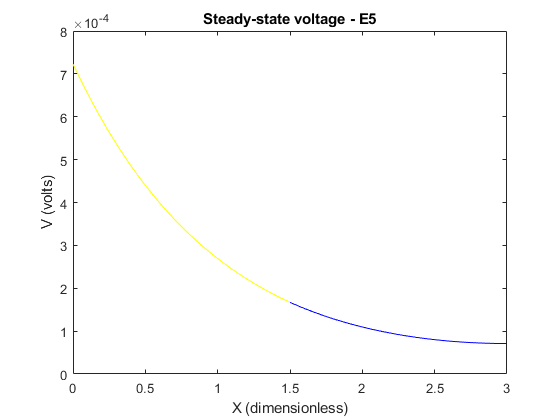

A_1=A;
A_1(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
A_1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_1\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

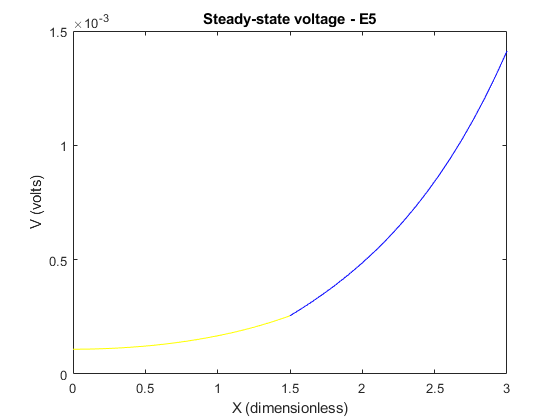

A_2=A;
b_2=b;
A_2(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
A_2(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
b_2(1) = 0; b_2(2) = rl21*iapp;
b_2(3) = rl22*iapp;
x_a=A_2\b_2;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

**The given image contains text explaining the significance of certain properties observed in graphs labeled 2(c) and 2(d). It mentions that the continuously differentiable nature of these graphs allows for smooth transmission of electrical impulses from the parent branch to daughter branches. Additionally, the negligible potential difference between the daughter branches in 2(d) ensures equal electrical impulse transmission to both branches. The text concludes that the observations provided are correct and complementary, offering a comprehensive explanation of the differences between the graphs.**